# One Patient

Analyze data about one patient:

- Extract EEG data

- Apply Laplacian filter and compute PSD

- Choose discriminant features using Fisher score

- Train and save a classifier

- Evaluate performance with and without evidence accumulation

clearvars; clc;
patients = find_patients('eeg');
patient = patients{1};
classifiers_fold_root = './classifiers/'

classifiers_fold_root = './classifiers/'


disp(strcat('Beginning data Analysis for patient: ', patient.name));

Beginning data Analysis for patient:ah7


info.fixation_code = 786;
info.cue_BH = 773;
info.cue_BF = 771;
info.cue_rest = 783;
info.feedback_code = 781;
info.offline_mode = 0;
info.online_mode = 1;

info.selected_frequencies = (4:2:48)';
info.channel_labels  = {'Fz', 'FC3', 'FC1', 'FCz', 'FC2', 'FC4', 'C3', 'C1', 'Cz', 'C2', 'C4', 'CP3', 'CP1', 'CPz', 'CP2', 'CP4'};
info.num_features = 3;

% Weights for channels and frequencies.
features_weight = load('features_filter.mat').features_filter';

## load EEG for online data - compute Laplacian referencing and PSD

PSD_data = cell(size(patient.online_files));
for f = 1:length(patient.online_files)
    % Raw EEG
    [s, h] = sload(patient.online_files{f});
    
    % Apply Lap and compute PSD
    PSD_data{f} = psd_extraction(s, h);
end

[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events


## common data

here we suppose the frequecies of the PSD don't change between the files

info.frequencies = PSD_data{1}.frequencies;
[PSD, EVENT, run_k] = concatenatePSD(PSD_data);

## label data

[cue_k, trial_k] = label_data(EVENT, length(PSD));

## log and sub-frequences extraction

[PSD, info.frequencies] = extract_frequencies(PSD, info.frequencies, info.selected_frequencies);
PSD = log(PSD); 

## load classifier data

load(strcat(classifiers_fold_root, patient.name, '_classifier'));

## convert PSD into dataset for the classifiers

dataset = extract_features(PSD, selected_features);

## extract test set

classes = [info.cue_BF, info.cue_BH];
bh_index = (cue_k== info.cue_BH);
bf_index = (cue_k== info.cue_BF);

test_set = dataset(bh_index | bf_index, :);
true_labels = cue_k(bh_index | bf_index);

## test the model on online data

predicted_labels = predict(model, test_set);
[accuracy, accuracy_per_class] = evaluate_classifier(true_labels, predicted_labels, classes)

accuracy = 73.4216

accuracy_per_class =    74.8002   72.5689


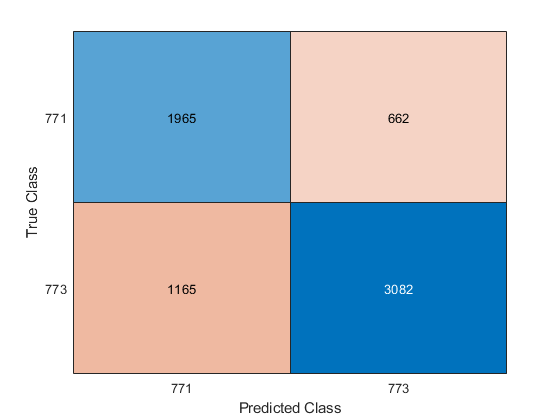

confusionchart(true_labels, predicted_labels);

# Evidence Accumulation

classify and accumulate evidence over the feedback period of online runs

the evidence accumulation is based on the posterior probability of class 771 both feet

## data

% online data
accumulation_data = dataset;
%predict on data
[~,post_probabilities] = predict(model, accumulation_data);

num_classes = length(classes);
% vector of start of feedback for each trial
feedback_starts = EVENT.POS(EVENT.TYP==info.feedback_code);

## Exponential smoothing accumulator from loaded parameters

accumulator_ex = exponential_smoothing(post_probabilities, num_classes, feedback_starts, exp_param.alpha);

## Dynamic smoothing accumulator from loaded parameters

% rebuild functions supposing we have choosen those two also in the tuning
free_force_function = @(x) f_free(x, dyn_param.conservative_amp, dyn_param.w);
bmi_force_function = @(x) f_bmi_sin(x);

accumulator_dyn = dynamic_smoothing(post_probabilities, num_classes, feedback_starts, dyn_param.alpha, dyn_param.beta, free_force_function, bmi_force_function);

## moving average accumulator from loaded parameters

accumulator_mov = mov_avg_smoothing(post_probabilities, num_classes, feedback_starts, mov_avg_param.alpha);

# EVIDENCE ACCUMULATION PERFORMANCE

## data


% index for the feedback part of the data used in accumulation
feedback_index = labels_for_event(EVENT, info.feedback_code, length(PSD));
% vector of true class for the trial
true_class = EVENT.TYP(EVENT.TYP==info.cue_BF | EVENT.TYP==info.cue_BH | EVENT.TYP==info.cue_rest);

## accuracy

[perf_active_ex, perf_resting_ex, perf_active_rej_ex] = evaluate_accumulation(exp_param.up_threshold, exp_param.down_threshold, true_class, accumulator_ex, feedback_index, trial_k)

perf_active_ex = 83.7500

perf_resting_ex = 17.5000

perf_active_rej_ex = 85.8974

[perf_active_dyn, perf_resting_dyn, perf_active_rej_dyn] = evaluate_accumulation(dyn_param.up_threshold, dyn_param.down_threshold, true_class, accumulator_dyn, feedback_index, trial_k)

perf_active_dyn = 76.2500

perf_resting_dyn = 2.5000

perf_active_rej_dyn = 77.2152

[perf_active_mov, perf_resting_mov, perf_active_rej_mov] = evaluate_accumulation(mov_avg_param.up_threshold, mov_avg_param.down_threshold, true_class, accumulator_mov, feedback_index, trial_k)

perf_active_mov = 67.5000

perf_resting_mov = 2.5000

perf_active_rej_mov = 67.5000